## Load Data

% Sinusoid data
load('Drop_+_sines.mat')
y1 = angular_velocity.data;
y2 = pendulum_angle.data;
u = stim_input_1;

% figure;
% y2 = y2 + 2*pi*ones(N,1);
% plot(t, y2)

data_start = 328;
y1 = y1(data_start:end);
y2 = y2(data_start:end);
t = t(data_start:end);
u = u(data_start:end);

N = size(t,2);

% Data pre-processing
y2 = y2 + 2*pi*ones(N,1);

y = zeros(N,1);
for i = 1:N
    y((i-1)*2+1:i*2) = [y1(i); y2(i)];
end

clearvars -except y y1 y2 u t N

## Apply PEM

theta0 = [-10000 100 2 0]';
theta = theta0;
lambda = 0;
maxiter = 500;
p = 4; % Number of parameters
h = 0.01;

% initialize
converged = false

converged = logical
   0


maxiter_reached = false;
iter = 1;

B = [4.1334; 0; 0];
C = [1 0 0; 0 1 0];
D = [0;0];

while ~converged && ~maxiter_reached 

    %%%%%% YOUR CODE HERE %%%%%%

    [Abar, x0] = theta2matrices(theta, h);
    [yhat, xhat] = simsystem_y_as_vec(Abar, B, C, D, x0, u);
    E = y - yhat;
    psi = psi_fun(xhat, x0, Abar, h);
    N_E = length(E);
    J = 2/N_E * psi' * E; % Jacobian
    N_H = size(psi,1);
    H = 2/N_H * (psi' * psi); % Hessian

    invLM = (H + lambda * eye(p))\eye(p); %Levenberg-Marquardt singularity inverse
    theta_new = theta - invLM * J;

    
    % Check convergence
    if norm(theta_new - theta) < 1e-6
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end   
new_parameter = theta(1)/h;


## Evaluate

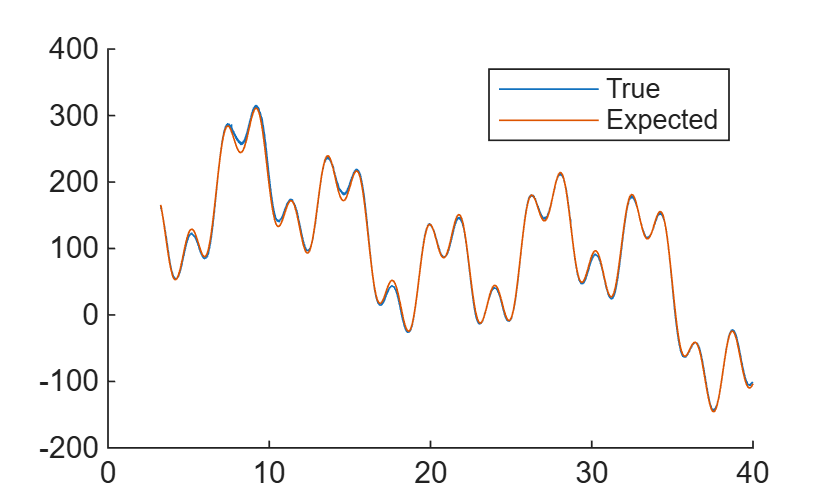

[y_est,~] = simsystem_y_as_vec(Abar, B, C, D, x0,u);

y_est1 = zeros(N,1);
y_est2 = zeros(N,1);

for i = 1:N
    y_est1(i) = y_est((i-1)*2+1);
    y_est2(i) = y_est(i*2);
end

figure;
hold on
plot(t,y1);
plot(t,y_est1);
legend('True', 'Expected')

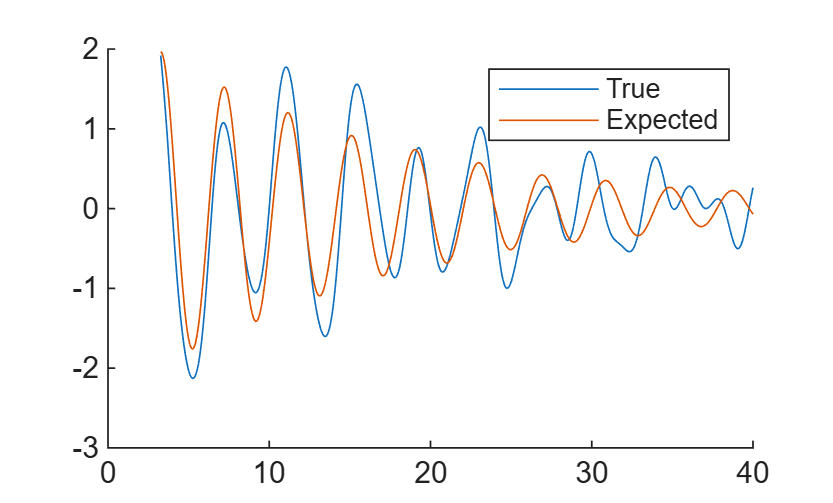


figure;
hold on
plot(t,y2);
plot(t,y_est2);
legend('True', 'Expected')

## PEM (functions)

function [Abar,x0] = theta2matrices(theta,h)
% Converts theta into matrices for a full parameterisation with n = 3, l =
% 2
% Function INPUT
% theta     Parameter vector (vector of size: according to the realization)
%
% Function OUTPUT
% Abar      System matrix A (matrix of size n x n)
% Bbar      System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)

%%%%%% YOUR CODE HERE %%%%%%
a1 = theta(1); x0 = theta(2:4);

Abar=[0.9904 0 0; 0 1 h; a1*h -0.0254 0.9985]; 
end

function psi = psi_fun(xhat, x0, Abar,h)

C = [1 0 0; 0 1 0];
% Dimensions
n = 3; l = 2;

% Derivative Definitions
dAbar1 = [0 0 0; 0 0 0; h 0 0];

dx02 = [1; 0; 0];
dx03 = [0; 1; 0];  
dx04 = [0; 0; 1];

N = size(xhat,1); 
p = 4; % 11 sub-parameters of theta
xhat = xhat'; % x coming in is Nxn, now is nxN

dx = zeros(n,p);
dy = zeros(l,p);
psi = zeros((N-1)*l,p);

% First iteration
dx1 = dAbar1*x0;

dx=[dx1 dx02 dx03 dx04];
for k = 2:N % xhat is 0 - N-1, 
    % dy / psi update
    for i = 1 : p
        dy(:,i) = C * dx(:,i);
    end
    psi((k-l)*l+1:(k-l)*l+l,:) = -dy; % psi is relative to -dyhat

    % dx update
    % A parameters
    dx(:,1) = Abar * dx(:,1) + dAbar1 * xhat(:,k);

    % x0 parameters
    dx(:,2) = Abar * dx(:,2);
    dx(:,3) = Abar * dx(:,3);
    dx(:,4) = Abar * dx(:,4);

end
psi = [zeros(2,p) ; psi]; % How to deal with dyhat0?
end

function [y,x] = simsystem_y_as_vec(A,B,C,D,x0,u)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
%
% Function INPUT
% A system matrix (matrix of size n x n)
% B system matrix (matrix of size n x m)
% C system matrix (matrix of size l x n)
% D system matrix (matrix of size l x m)
% x0 initial state (vector of size n x one)
% u system input (matrix of size N x m)
%
% Function OUTPUT
% x state of system (vector of size N x n)
% y system output (matrix of size N x l)

% YOUR CODE HERE

N = length(u);
n = length(x0);
l = size(C,1);
x = zeros(n, N);
y = zeros(l*N,1);

x(:,1) = x0;
y(1:2) = C * x(:,1) + D * u(1);

for k = 2:N
    x(:,k) = A * x(:,k-1) + B * u(k-1);
    y((k-1)*l+1:k*l) = C * x(:,k) + D * u(k);
end

x = x';
end